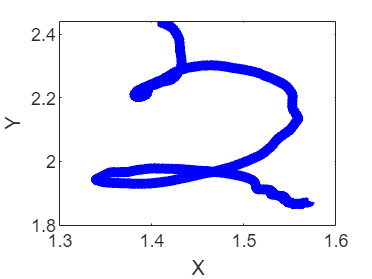

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
%data_cw = load("retake_one.mat");
data_cw = load("centri_six.mat");
%data_cw = load("accro_one_two.mat");
data_cw_one = load("accro_two_one.mat");
%data_cw = load("test_two.mat");
%data_cw = load("control_test.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

start = 1;
last = 300; 
radius = 0.5;

% compare w the quadrant from test_aux, do a graph comparing heading
% differences

x_cw = (data_cw.unnamed(start:last,1));
y_cw = (data_cw.unnamed(start:last,2)) + 4.5;
z_cw = (data_cw.unnamed(:,3));
heading = rad2deg((data_cw.unnamed(start:last,4))); % 1 round in control inputs is 80 pts, but reality wise is 320 pts for some reason
time = (data_cw.unnamed(start:last,5));
a = size(heading);

% x_cw_one = (data_cw_one.unnamed(start:last,1));
% y_cw_one = (data_cw_one.unnamed(start:last,2));
% z_cw_one = (data_cw_one.unnamed(:,3));
% heading_one = rad2deg((data_cw_one.unnamed(start:last,4))); % 1 round in control inputs is 80 pts, but reality wise is 320 pts for some reason
% a_one = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

r_x = x_cw;
r_y = y_cw;
rad_data = radius - sqrt((r_x).^2 + (r_y).^2);
counter_des = 0;
counter_actl = 0;


figure(1)
plot(y_cw,x_cw,'Color','blue','linewidth',5)
xlabel('X')
ylabel('Y')

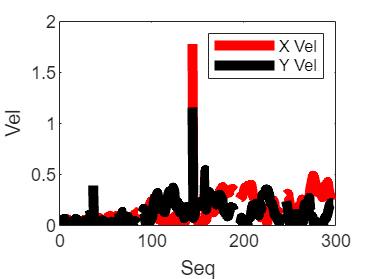


% hold on
% %plot(x_cw_one,y_cw_one,'Color','red','linewidth',5)
% plot(x_r,y_r,'Color','black','linewidth',5)
% 
% xlabel('X')
% ylabel('Y')
limit = size(heading);
vel = zeros(3,limit(1));
comp_heading = zeros(3,limit(1));
% % legend('Two','One','Ref')
% hold off


for i = 1:limit(1)

    if heading(i,1) > 176
        counter_des = counter_des + 1;
    end

    if limit(1) > i
        vel(1,i) = abs(x_cw(i+1,1) - x_cw(i,1))/abs(time(i+1,1) - time(i,1));  
        vel(2,i) = abs(y_cw(i+1,1) - y_cw(i,1))/abs(time(i+1,1) - time(i,1));        
        comp_heading(1,i) = rad2deg(atan2((y_cw(i+1,1) - y_cw(i,1)),(x_cw(i+1,1) - x_cw(i,1))));
    end

    if comp_heading(1,i) == 180
        counter_actl = counter_actl + 1;
    end
    
end


for i = 1:limit(1)-1

    if (limit(1)-1) > i
        comp_heading(2,i) = abs(comp_heading(1,i+1) - comp_heading(1,i))/(time(i+1,1)-time(i,1));
        comp_heading(3,i) = abs(heading(i+1,1) - heading(i,1))/(time(i+1,1)-time(i,1));
    end
        
end

comp_heading(2,:) = medfilt1(comp_heading(2,:),'omitnan','truncate');
comp_heading(3,:) = medfilt1(comp_heading(3,:),'omitnan','truncate');
A = abs(comp_heading(:,1:100));
A = A(:, all(~(((isnan(A)|isinf(A)))|A==0), 1));
%A = A(:,all(~A==0,1));

heading_diff = transpose(heading) - comp_heading(1,:);

%lp = lowpass((comp_heading(2,1:32)/10^4),0.2,3);
lp_a = lowpass((A(2,1:91))/10^4,0.2,5); % lowpass yaw rate actual 
lp_d = lowpass((A(3,1:91))/10^4,0.2,5); % lowpass yaw rate desired
lp_c = lp_d - lp_a; % lowpass yaw rate difference

plot(1:a(1),vel(1,:),'Color','red','linewidth',5)
hold on
plot(1:a(1),vel(2,:),'Color','black','linewidth',5)
xlabel('Seq')
ylabel('Vel')
legend('X Vel','Y Vel')
hold off

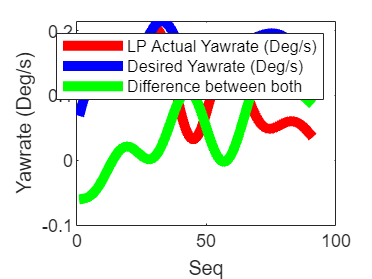


plot(1:91,lp_a,'Color','red','linewidth',5)
hold on
plot(1:91,lp_d,'Color','blue','linewidth',5)
plot(1:91,lp_c,'Color','green','linewidth',5)
xlabel('Seq')
ylabel('Yawrate (Deg/s)')
legend('LP Actual Yawrate (Deg/s)','Desired Yawrate (Deg/s)','Difference between both')
hold off


fprintf('Desired (%d) vs Actual (%d)', counter_des, counter_actl);

Desired (12) vs Actual (2)

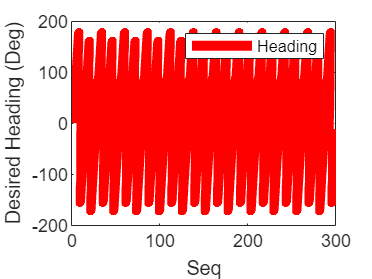

plot(1:a(1),heading,'Color','red','linewidth',5)
xlabel('Seq')
ylabel('Desired Heading (Deg)')
legend('Heading')

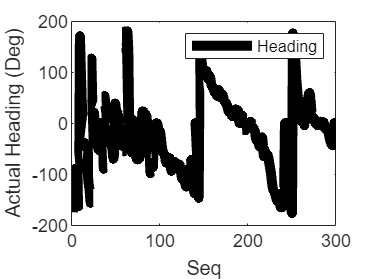


plot(1:a(1)-1,comp_heading(1,1:a(1)-1),'Color','black','linewidth',5)
xlabel('Seq')
ylabel('Actual Heading (Deg)')
legend('Heading')

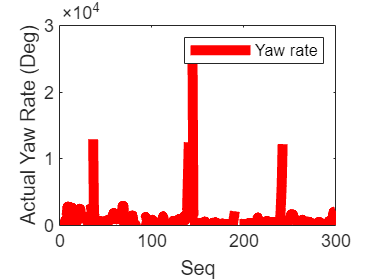


plot(1:a(1)-2,comp_heading(2,1:a(1)-2),'Color','red','linewidth',5)
xlabel('Seq')
ylabel('Actual Yaw Rate (Deg)')
legend('Yaw rate')

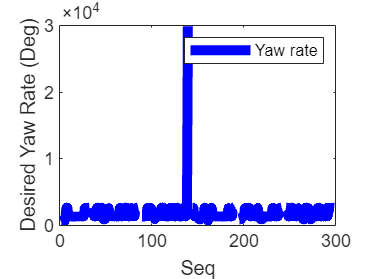


plot(1:a(1)-2,comp_heading(3,1:a(1)-2),'Color','blue','linewidth',5)
xlabel('Seq')
ylabel('Desired Yaw Rate (Deg)')
legend('Yaw rate')

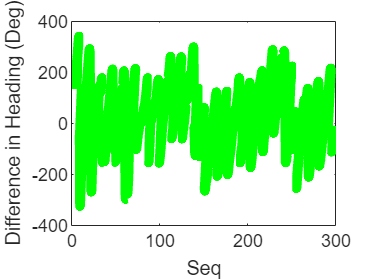


plot(1:a(1),heading_diff,'Color','green','linewidth',5)
xlabel('Seq')
ylabel('Difference in Heading (Deg)')

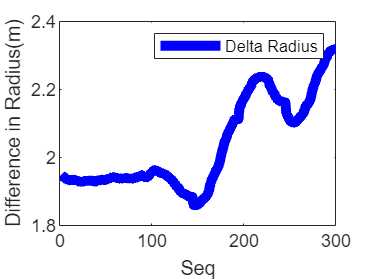


plot(1:a(1),abs(rad_data),'Color','blue','linewidth',5)
xlabel('Seq')
ylabel('Difference in Radius(m)')
legend('Delta Radius')

% Gaussian Process
size(lp_a)

ans =      1    91


size(lp_c)

ans =      1    91


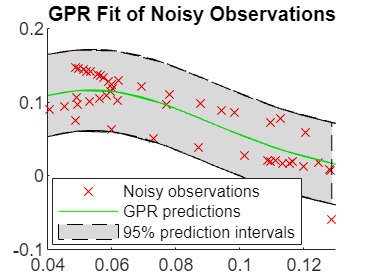

% gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl1 = fitrgp(transpose(lp_a),transpose(lp_c));
% x_test = linspace(0,0.15,15)';
x_test = transpose(lp_a);

%predict(gprMdl1,0.15)

[ypred1,ysd,yint1] = predict(gprMdl1,x_test);
%yint1(:,1) = 5 percentile, (:,2) is for 95 percentile

scatter(transpose(lp_a),transpose(lp_c),'xr') % Observed data points
hold on
plot(x_test,ypred1,'g') % GPR predictions
patch([x_test;flipud(x_test)],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.15,'LineStyle','--'); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations','GPR predictions','95% prediction intervals'},'Location','best')
xlim([0.04 0.13])
ylim([-0.100 0.2])

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_one_state.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

x_cw = (data_cw.retake_one_state(1:420,1));
y_cw = (data_cw.retake_one_state(1:420,2));
z_cw = (data_cw.retake_one_state(:,3));
heading = rad2deg((data_cw.retake_one_state(1:420,4)));
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake W State_1','Ref')
hold off

plot(1:a(1),abs(heading),'Color','red','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Heading')

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_two.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

x_cw = (data_cw.retake_two(:,1));
y_cw = (data_cw.retake_two(:,2));
z_cw = (data_cw.retake_two(:,3));
heading = rad2deg((data_cw.retake_two(1:420,4)));
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake WO State 2','Ref')
hold off

plot(1:a(1),abs(heading),'Color','red','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Heading')

clear; % clears all var
clc; % clears command window
data_ref = load("ref.mat");
data_cw = load("retake_two_state.mat");
%data_ccw = load("ccw_video.mat");
%data = load("first_successful.mat");

x_cw = (data_cw.retake_two_state(1:420,1));
y_cw = (data_cw.retake_two_state(1:420,2));
z_cw = (data_cw.retake_two_state(:,3));
heading = rad2deg((data_cw.retake_two_state(1:420,4)));
a = size(heading);

x_r = (data_ref.C3(11,:));
y_r = (data_ref.C3(12,:));
z_r = (data_ref.C3(13,:));

figure(1)
plot(x_cw,y_cw,'Color','blue','linewidth',5)

hold on

plot(x_r,y_r,'Color','black','linewidth',5)

xlabel('X')
ylabel('Y')
legend('Retake W State_2','Ref')
hold off

plot(1:a(1),abs(heading),'Color','red','linewidth',5)




xlabel('X')
ylabel('Y')
legend('Heading')